Extract pre-recorded data. IMPORTANT: change path name to the path of test data on your computer

path = "/Users/baswarajswamy/AirBeats/MATLAB files/timed_readings.txt";
mpudata = readtable(path);
mpudata.Properties.VariableNames = ["Time", "GyroX", "GyroY", "GyroZ", "AccelX", "AccelY", "AccelZ"]

mpudata = 391×7 table
    Time    GyroX    GyroY    GyroZ    AccelX    AccelY    AccelZ
    ____    _____    _____    _____    ______    ______    ______

    0.01    -0.28    -0.08    0.23      0.09         0      0.88 
    0.21    -0.31     0.01    0.21      0.09         0      0.89 
    0.42    -0.28    -0.16    0.24      0.09         0      0.89 
    0.62     -0.3     0.25    0.22      0.09      0.01      0.89 
    0.83    -0.27    -0.27    0.23      0.09      0.01      0.88 
    1.03    -0.28     0.14    0.22      0.09         0      0.88 
    1.24    -0.29     0.02    0.23      0.09         0      0.89 
    1.44     -0.3    -0.11    0.21      0.09      0.01      0.88 
    1.65    -0.31     0.19    0.24      0.09         0      0.88 
    1.86    -

Lets see how the GyroX data looks

plot(mpudata.Time, mpudata.GyroX, "b")
p = polyfit(mpudata.Time(1:100, 1), mpudata.GyroX(1:100, 1), 1);
hold on
OrientX = zeros(391,1);
% If you can improve this code please do
for c = 2:391
    OrientX(c) = OrientX(c-1) + (mpudata.Time(c) - mpudata.Time(c-1))*(mpudata.GyroX(c-1));
end
plot(mpudata.Time, OrientX(1:391), "r")
xlabel("Time [s]")
ylabel("Degrees")
legend("readingX", "orientationX")
hold off

Not much insight (rather than the curve slanting downwards), but lets look at the first 20 seconds or so when the sensor is supposed to be stationary

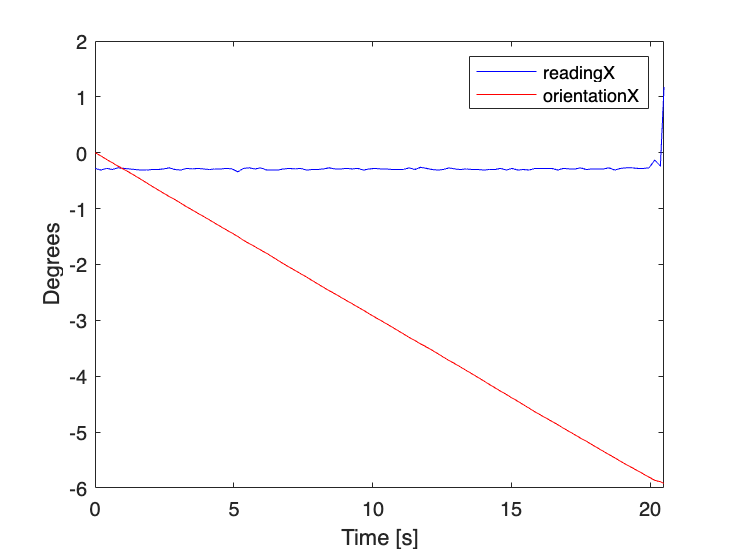

xlim([0 20.5])

This is when the sensor drift (or bias) becomes apparent. Even in a stationary setting, the sensor seems to indicate that there is some rotation in the x-direction. Let us look at the other axes as well.

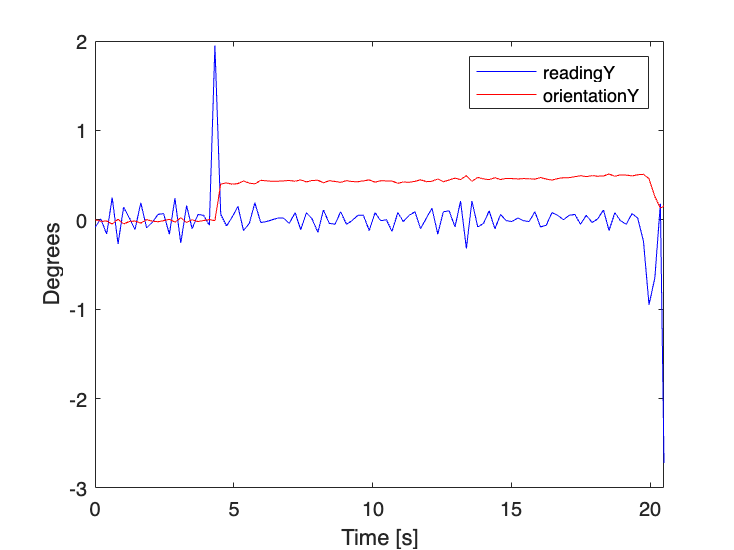

OrientY = zeros(391,1); OrientZ = zeros(391,1);
for c = 2:391
    OrientY(c) = OrientY(c-1) + (mpudata.Time(c) - mpudata.Time(c-1))*(mpudata.GyroY(c-1));
    OrientZ(c) = OrientZ(c-1) + (mpudata.Time(c) - mpudata.Time(c-1))*(mpudata.GyroZ(c-1));
end

plot(mpudata.Time, mpudata.GyroY, "b")
hold on
plot(mpudata.Time, OrientY, "r")
legend("readingY", "orientationY")
xlim([0 20.5])
xlabel("Time [s]")
ylabel("Degrees")
hold off

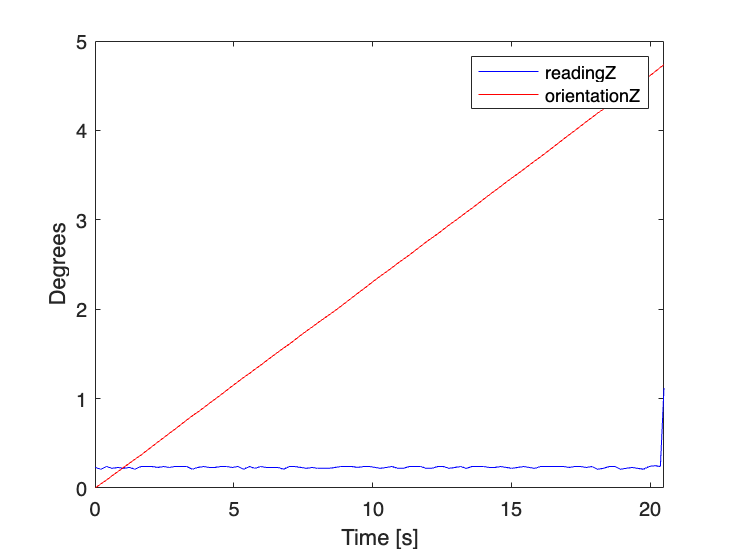


plot(mpudata.Time, mpudata.GyroZ, "b")
hold on
plot(mpudata.Time, OrientZ, "r")
legend("readingZ", "orientationZ")
xlim([0 20.5])
xlabel("Time [s]")
ylabel("Degrees")
hold off

From this we can see that GyroX has a negative bias, GyroY has a neutral (?) bias, and GyroZ has a positive bias. How do we fix thisssssss?

One thing we can try is reject all readings in the range of the bias.

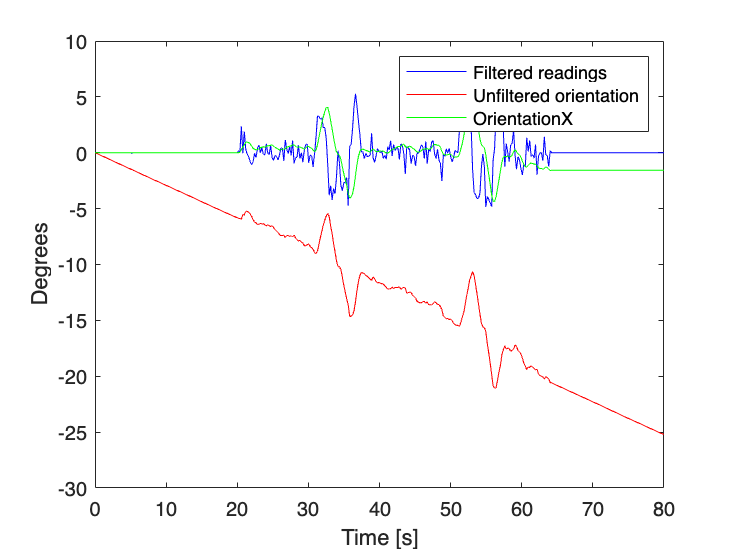

GyroX = mpudata.GyroX + 0.30; GyroY = mpudata.GyroY + 0.1; GyroZ = mpudata.GyroZ - 0.225;

% Reject all readings in drift range
GyroX((GyroX >= -0.04) & (GyroX <= 0.04)) = 0;
GyroY((GyroY >= -0.3) & (GyroY <= 0.3)) = 0;
GyroZ((GyroZ >= -0.025) & (GyroZ <= 0.025)) = 0;

% Calculate orientation with filtered values now
filterX = zeros(391, 1); filterY = zeros(391, 1); filterZ = zeros(391,1);
for c = 2:391
    filterX(c) = filterX(c-1) + (mpudata.Time(c) - mpudata.Time(c-1))*(GyroX(c-1)+GyroX(c))/2;
    filterY(c) = filterY(c-1) + (mpudata.Time(c) - mpudata.Time(c-1))*(GyroY(c-1)+GyroY(c))/2;
    filterZ(c) = filterZ(c-1) + (mpudata.Time(c) - mpudata.Time(c-1))*(GyroZ(c-1)+GyroZ(c))/2;
end

% Plot X-axis data
plot(mpudata.Time, GyroX, "b")
hold on
plot(mpudata.Time, OrientX, "r")
plot(mpudata.Time, filterX, "g")
legend("Filtered readings", "Unfiltered orientation", "OrientationX")
xlabel("Time [s]")
ylabel("Degrees")
xlim([0 80])
hold off

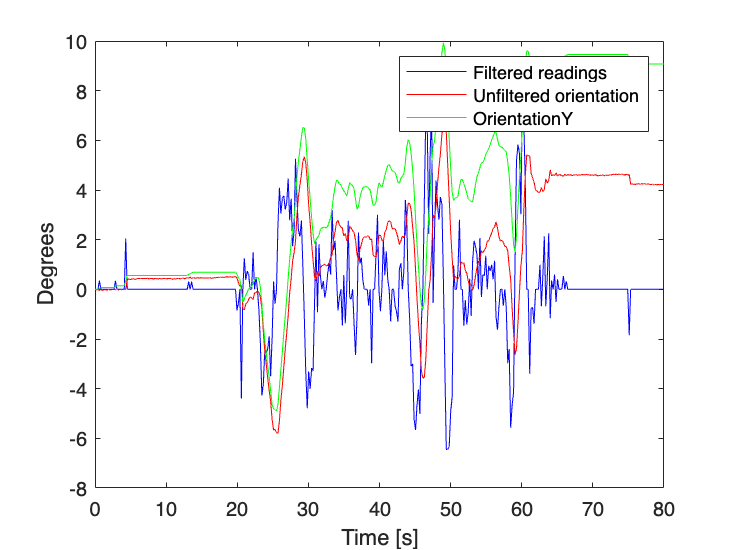


% Plot Y-axis data
plot(mpudata.Time, GyroY, "b")
hold on
plot(mpudata.Time, OrientY, "r")
plot(mpudata.Time, filterY, "g")
legend("Filtered readings", "Unfiltered orientation", "OrientationY")
xlabel("Time [s]")
ylabel("Degrees")
xlim([0 80])
hold off

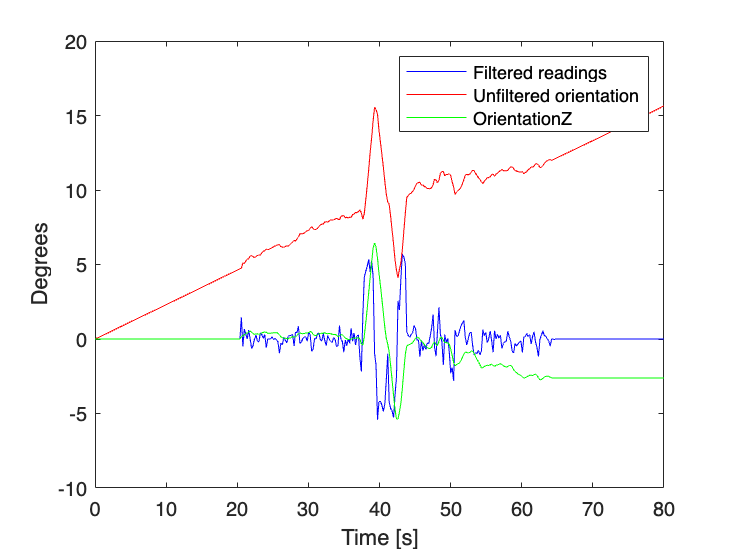


% Plot Z-axis data
plot(mpudata.Time, GyroZ, "b")
hold on
plot(mpudata.Time, OrientZ, "r")
plot(mpudata.Time, filterZ, "g")
legend("Filtered readings", "Unfiltered orientation", "OrientationZ")
xlabel("Time [s]")
ylabel("Degrees")
xlim([0 80])
hold off

Well that looks like an improvement (y axis wildin). However this is very jugadoo and we haven't really tested it out with a model yet. Our first task should be to implement a 3D model for atleast the orientation.

Let us save some variables and start work on the model.

save orient_dat.mat OrientX OrientY OrientZ filterX filterY filterZ